# **Simulationsstudie**

# *Lange Pneumatikleitung: Nord Stream 2 Pipline im isothermen Fall*

clear, clc, close all;

## 1. Eingabe der Simulationsparameter

Rohreigenschaften:

ri =0.577;     % Leitungsinnenradius [m] ; (NordStream2: 0.577m)
AL=pi*ri^2;                   % Querschnittsfläche der Leitung bei ri=const [m^2]
k  =0.000001;     % Absolute Rauheit der Rohrleitung [m] ; (NordStream2: 1e-6)
    % Innenbeschichtung der Stahlrohre: Antifriktions-Hochglanzlackierung auf Epoxidbasis
    % --> technisch glattes Rohr: k=1 Mikrometer 
lambda=1/(-2*log10(k/(3.71*2*ri)))^2;     % Rohrwiderstandsbeiwert für ein hydraulisch raues Rohr nach der Formel von Nikursade [keine Einheit]

n=50;  % Anzahl ORTS-Diskretisierungspunkte (Anzahl Rohrstücke)
LL= 1230000;     % Gesamtlänge der Pipeline [m] ; (NordStream2: 1.230.000m)
LSeg=LL/n;                    % Länge eines Leitungssegments [m]
VSeg=LSeg*AL;                 % Volumen eines Leitungssegments [m^3]
VLL=linspace(0,LL,n)';        % Gesamtlänge als Vektor mit n gleichgroßen Abständen [m]

Parameter der Simulationszeit:

ta= 0;                                              % Startzeitpunkt für Simulation
te=2.5*60*60*24;  % Endzeitpunkt für Simulation (Umrechnung in Sekunden)
dt=1;                        % Zeitinkrement in Sekunden
t=(ta:dt:te)';                                      % Vektor der ZEIT-Diskretisierungspunkte (Spaltenvektor von 0 bis te im Abstand von dt)

Szenarium auswählen:

Fluid="[g]_Methan_CH4"; % Rs und ny werden automatisch für das ausgewählte Fluid benutzt
switch Fluid
    case "[g]_Methan_CH4"  % NordStream2: russisches H-Erdgas besteht bis zu 99% aus Methan
        Rs=0.5183e3;       % Spez. Gaskonstante [J/(kg*K)]
        ny=14.2e-6;        % kinematische Viskosität des Fluids [m^2/s]
    case "[g]_Ethan_C2H6"
        Rs=0.2765e3;       % Spez. Gaskonstante [J/(kg*K)]
        ny=6.37e-6;        % kinematische Viskosität des Fluids [m^2/s]
    case "[g]_Propan_C3H8"
        Rs=0.1896e3;       % Spez. Gaskonstante [J/(kg*K)]
        ny=3.73e-6;        % kinematische Viskosität des Fluids [m^2/s]
end

Eingangsdruck=220;% [bar]  % von der Pumpe erzeugter konstanter Eingangsdruck ; (NordStream2: 220bar)
p_in=Eingangsdruck*10^5;                          % Umrechnung des Eingangsdrucks von bar nach Pa

Gas_Temperatur=7;% [°C]   % konstante Temperatur des Fluids während der gesamten Simulation (Durchschnitt Ostsee: 7°C)
T0=273.15 + Gas_Temperatur;                       % Umrechnung der Temperatur des Fluids von °C nach K

Stroemungsart="turbulent";    % Auswahl der Strömungsart zwischen <laminar> oder <turbulent>
LeitungEnde=  "LeitungGeschlossen";    % Auswahl des Leitungsendes zwischen <offen> oder <geschlossen>

Für ein realistisch-turbulentes Systemverhalten wird der Strömungswiderstand über den Rohrwiderstandsbeiwert berechnet.

Zur Vergleichbarkeit zwischen turbulenter und laminarer Strömung werden die jeweiligen Massenströme im stationären Zustand gleichgesetzt.

Daraus ergibt sich ein turbulenter Strömungswiderstand, aus dem ein vergleichbares turbulentes Systemverhalten zum laminaren Szenario resultiert.

R_lam=(32*ny*LSeg)/(AL*(2*ri)^2);        % Strömungswiderstand für laminare Strömung [1/(m*s)]
R_turb_Verhalten= "real";  % Auswahl des turbulenten Widerstands zwischen <realistisch> oder <vergleichbar zu laminar>
switch R_turb_Verhalten
    case "real"
        R_turb=(lambda*LSeg*Rs*T0)/(4*ri*AL^2); % Realistisch berechneter Strömungswiderstand für rau-turbulente Strömung [1/(m*s)^2]
    case "vergl_lam"
        R_turb=R_lam^2;                         % Zum laminaren Fall vergleichbarer Strömungswiderstand für rau-turbulente Strömung [1/(m*s)^2]
end
L=LSeg/AL;                             % Pneumatische Induktivität [1/m]
Cap=VSeg/(Rs*T0);                      % Pneumatische Kapazität [m*s^2]

## 2. Definition der Modellgleichung als lineares Differential-Gleichungssystem

### 2.1. Mathematische Modellbildung

                      **Form der DGL**        $\dot{x} =A\cdot x+B\cdot u$

**Systembeschreibende DGL**      $\dot{x} =\left(\begin{array}{c}
\underline{\ddot{m} } \\
\underline{\dot{p} } 
\end{array}\right)=\left\lbrack \begin{array}{cc}
U & V\\
W & 0
\end{array}\right\rbrack \cdot \left(\begin{array}{c}
\underline{\dot{m} } \\
\underline{p} 
\end{array}\right)+\left(\begin{array}{c}
B
\end{array}\right)\cdot p_{\textrm{in}}$

**Systemmatrizen A,B**                   Matrix $A=\left\lbrack \begin{array}{cc}
U & V\\
W & 0
\end{array}\right\rbrack$            Matrix $B=\left\lbrack \begin{array}{c}
\frac{1}{L}\\
0\\
\vdots \\
0
\end{array}\right\rbrack$

*        Dimensionen der Systemmatrizen:*     $A\in \Re^{2N\times 2N}$                                $B\in \Re^{2N}$ 

**Teilmatrizen U,V,W**        $U=\left\lbrack \begin{array}{ccc}
-\frac{R}{L} &  & 0\\
 & \ddots  & \\
0 &  & -\frac{R}{L}
\end{array}\right\rbrack$        $V=\left\lbrack \begin{array}{ccccccc}
-\frac{1}{L} & 0 &  &  &  &  & 0\\
\frac{1}{L} & \ddots  & \ddots  &  &  &  & \\
 & \ddots  & \ddots  & \ddots  &  &  & \\
 &  & \frac{1}{L} & -\frac{1}{L} & 0 &  & \\
 &  &  & \ddots  & \ddots  & \ddots  & \\
 &  &  &  & \ddots  & \ddots  & 0\\
0 &  &  &  &  & \frac{1}{L} & -\frac{1}{L}
\end{array}\right\rbrack$        $W=\left\lbrack \begin{array}{cccc}
\frac{1}{C} & -\frac{1}{C} &  & 0\\
0 & \ddots  & \ddots  & \\
 & \ddots  & \ddots  & -\frac{1}{C}\\
0 &  & 0 & \frac{1}{C}
\end{array}\right\rbrack$    

*        Dimensionen der Teilmatrizen:*      $U,V,W\in \Re^{N\times N}$

### 2.2. Programmentwicklung des mathematischen Modells

Schritt 1: Definition der Teilmatrizen

U=-diag((R_lam/L)*ones(1,n),0);
V=diag((1/L)*ones(1,n-1),-1)-diag((1/L)*ones(1,n),0);
W=diag((1/Cap)*ones(1,n),0)-diag((1/Cap)*ones(1,n-1),1);

if LeitungEnde == "LeitungOffen"    
    V(:,n)=0;   % Druck am Ende des letzten Leitungssegments: p_n+1=0 ==> Letzter Eintrag im Zustandsvektor: x(2*n)=!0
                % ==> letzte Spalte der Teilmatrix V =!0
    W(n,:)=0;   % Druckänderung am Ende des letzten Leitungssegments: p°_n+1=0 ==> Letzter Eintrag im Zustandsvektor: x°(2*n)=!0                    
                % ==> letzte Zeile der Teilmatrix W =!0
end

Schritt 2: Definition der Systemmatrizen

B=zeros(2*n,1);
B(1,1)=1/L;

A=[U,V;W,zeros(n,n)];

C1=[eye(n) zeros(n,n)]; % Über C1 wird in lsim nur die obere Hälfte (Massenströme) der Lösungsmatrix ausgegeben
C2=[zeros(n,n) eye(n)]; % Über C2 wird in lsim nur die untere Hälfte (Drücke) der Lösungsmatrix ausgegeben
D=zeros(n,1);           % Durchgangsmatrix für ss (State-space-model): D=0 ==> Keine Wirkung des Eingangssignals auf das Ausgangssignal

Schritt 3: Lösen des linearen Differential-Gleichungssystems

P=p_in*ones(length(t),1);           % Vektor des Eingangssignals für lsim mit p_in auf allen Zeilen

Y_lin1 = lsim(ss(A,B,C1,D),P,t)';   % Lösung des Zustandsraummodells: Massenströme über die Leitungssegmente (Zeilen) und Simulationszeitpunkte (Spalten)
Y_lin2 = lsim(ss(A,B,C2,D),P,t)';   % Lösung des Zustandsraummodells: Drücke über die Leitungssegmente (Zeilen) und Simulationszeitpunkte (Spalten)
Y_lin=[Y_lin1;Y_lin2];              % Darstellung der Gesamtlösung: Massenströme und Drück über die Leitungssegmente (Zeilen) und Simulationszeitpunkte (Spalten)

## 3. Definition der Modellgleichung für ein Lösungsverfahren mittels ode-solver

Auswahl eines solvers:

use_ODE="ode45";   % Auswahlmöglichkeit, welcher solver verwendet werden soll
X0=zeros(2*n,1);                % Leerer Zustandsvektor als Anfangsbedingung für den solver
opts=odeset('RelTol',1e-3,'AbsTol',1e-4,'MaxStep',1);   % Vorgabe der relativen und absoluten Fehler-Toleranz, sowie der maximalen Schrittweite
                                                          % RelTol:  Relativ zur Größe der jeweiligen Lösungskomponente
                                                          % AbsTol:  Lösungen unterhalb der AbsTol-Grenze werden als unwichtig erachtet
                                                          % MaxStep: Begrenzung der maximalen Schrittweite des solvers auf 1 Sekunde
switch use_ODE
    case "ode45"                
        sol=ode45(@(t,x_aktuell)DGL(t,x_aktuell,LeitungEnde,L,R_lam,R_turb,Cap,n,p_in,Stroemungsart),t,X0,opts);    % Numerische Lösung mittels ode45
    case "ode113"   
        sol=ode113(@(t,x_aktuell)DGL(t,x_aktuell,LeitungEnde,L,R_lam,R_turb,Cap,n,p_in,Stroemungsart),t,X0,opts);   % Numerische Lösung mittels ode113
end

% Y_solver=deval(sol,t,1:2*n);   % Ausgabe der interpolierten Lösungsmatrix des ode solvers zu vorgegebenen Zeitpunkten (Zeilen: Zustandsgrößen, Spalten: Zeitpunkte)
    % Fehler bei Verwendung von deval (Zeile 132)
    % Es wurde versucht, die Lösung außerhalb des Intervalls [0.000000e+00, 1.616694e+05] auszuwerten, in dem sie definiert ist.

Y_solver=sol.y;                 % Ausgabe der Lösungsmatrix des ode solvers (Zeilen: Zustandsgrößen, Spalten: Zeitpunkte)
t_solver=sol.x;                 % Ausgabe des  Zeitvektors  des ode solvers (Spalten: Zeitpunkte)

## 4. Visualisierung der Simulationsergebnisse

In den nachfolgenden Diagrammen werden die beiden berechneten Zustandsgrößen *Massenstrom* und *dynamischer Druck* des Fluids visualisiert.

Das Lösungverfahren, welches betrachtet werden soll:

plots_lin=true; plots_num=true;     % Lösung mittels linearem System in Zustandsraumform anzeigen ; % Lösung mittels numerischem Verfahren anzeigen

2D-Diagramme darstellen für:

plots2d_Seg=true;       % Visualisieren der Lösung für ein spezifisches Leitungssegment über die gesamte Simulationszeit
plots2d_t=true;         % Visualisieren der Lösung zu einem spezifischen Simulationszeitpunkt über die gesamte Leitung

3D-Diagramme darstellen für:

plots3d=false;           % 3D-Plots anzeigen

Die beiden Lösungsverfahren gegenüberstellen und 2D-Diagramme darstellen:

plots_vergl_Seg=true;   % Gegenüberstellung der Ergebnisse des num. Verfahrens und dem lin. DGL-System für ein spezifisches Leitungssegment über gesamte Simulationszeit
plots_vergl_t=true;     % Gegenüberstellung der Ergebnisse des num. Verfahrens und dem lin. DGL-System zu einem spezifischen Simulationszeitpunkt über die gesamte Leitung

t_Sim_prznt=85;     % Betrachteter Simulationszeitpunkt in % der Simulationszeit
t_Sim=round((t_Sim_prznt/100)*length(t));   % Zum betrachteten Simulationszeitpunkt zugehöriger ZEIT-Diskretisierungspunkt des Vektors t

i_Sim=1;            % Betrachtetes Leitungssegment

%%% richtige Bezeichnung der x-Achsenbeschriftung der Zeitachsen in den Plots
if te<=2.5
    xAchseEinheit=1;
    xAchseLabel='Zeit t [sec]';
elseif te/60<=2.5
    xAchseEinheit=60;
    xAchseLabel='Zeit t [min]';
else
    xAchseEinheit=3600;
    xAchseLabel='Zeit t [h]';
end

xAchse_lin=t/xAchseEinheit;
xAchse_num=t_solver/xAchseEinheit;

%%% Variablen für die jeweiligen Farben der Kurven
farbe_lin_m='#4DBEEE';      % lin. DGL-System Massenstrom
farbe_lin_p='#0072BD';      % lin. DGL-System Druck
farbe_num_m='#EDB120';      % jeweiliger ode-solver Massenstrom
farbe_num_p='#D95319';      % jeweiliger ode-solver Druck

### 4.1. Lösung mittels linearem DGL-System

#### 2D-Plot des rein linearen DGL-Systems

Visualisieren der Lösung für **ein** spezifisches Leitungssegment über die **gesamte** Simulationszeit

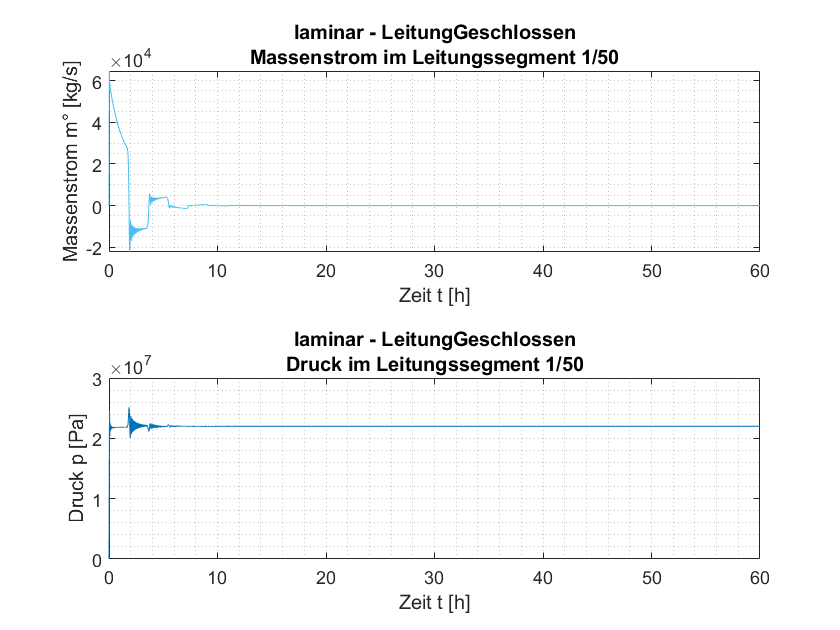

if plots_lin == true
    if plots2d_Seg == true
        tiledlayout(2,1)
    %%% Massenstrom Y_lin1
        Massenstrom_Y_lin1_SEG=nexttile;
        plot(Massenstrom_Y_lin1_SEG,xAchse_lin,Y_lin1(i_Sim,:),'Color',farbe_lin_m);
        title({"laminar - " + LeitungEnde;"Massenstrom im Leitungssegment " + i_Sim + "/" + n})
        grid minor
        xlabel(xAchseLabel)
        ylabel('Massenstrom m° [kg/s]')
    
    %%% Druck Y_lin2
        Druck_Y_lin2_SEG=nexttile;
        plot(Druck_Y_lin2_SEG,xAchse_lin,Y_lin2(i_Sim,:),'Color',farbe_lin_p)
        title({"laminar - " + LeitungEnde;"Druck im Leitungssegment " + i_Sim + "/" + n})
        grid minor
        xlabel(xAchseLabel)
        ylabel('Druck p [Pa]')
    else
        fprintf("Dieses Diagramm ist nicht ausgewählt!");
    end
else
    fprintf("Dieses Diagramm ist nicht ausgewählt!");
end

Visualisieren der Lösung über **alle** Leitungssegmente an **einem** spezifischen Simulationszeitpunkt

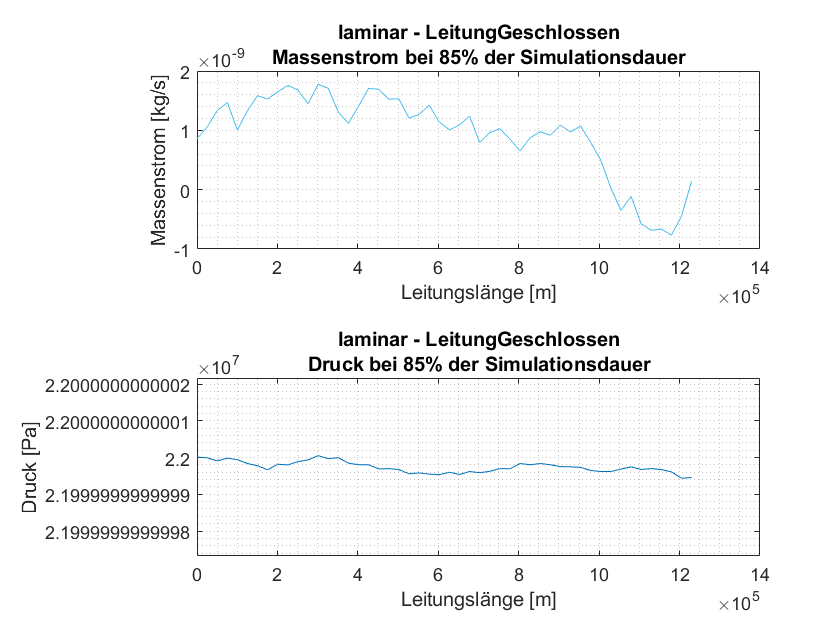

if plots_lin == true
    if plots2d_t == true
        tiledlayout(2,1)
    %%% Massenstrom Y_lin1
        Massenstrom_Y_lin1_TE=nexttile;
        plot(Massenstrom_Y_lin1_TE,VLL,Y_lin1(:,t_Sim),'Color',farbe_lin_m)
        title({"laminar - " + LeitungEnde;"Massenstrom bei " + t_Sim_prznt + "% der Simulationsdauer"})
        grid minor
        xlabel('Leitungslänge [m]')
        ylabel('Massenstrom [kg/s]')
    
    %%% Druck Y_lin2
        Druck_Y_lin2_TE=nexttile;
        plot(Druck_Y_lin2_TE,VLL,Y_lin2(:,t_Sim),'Color',farbe_lin_p)
        title({"laminar - " + LeitungEnde;"Druck bei " + t_Sim_prznt + "% der Simulationsdauer"})
        grid minor
        xlabel('Leitungslänge [m]')
        ylabel('Druck [Pa]')
    else
        fprintf("Dieses Diagramm ist nicht ausgewählt!");
    end
else
    fprintf("Dieses Diagramm ist nicht ausgewählt!");
end

#### 3D-Plot des rein linearen DGL-Systems

if plots_lin == true
    if plots3d == true
    %%% Massenstrom Y_lin1
        [T,N]=meshgrid(t,VLL);
        figure('Name',"Verlauf Massenstrom - laminar - " + LeitungEnde )
        mesh(T,N,Y_lin1)
        xlabel('Zeit t [h]');
        ylabel('Leitungslänge [m]');
        zlabel("Massenstrom [kg/s]"); 
        view([-41.400 36.600])
    
    %%% Druck Y_lin2
        [T,N]=meshgrid(t,VLL);
        figure('Name',"Verlauf Druck - laminar - " + LeitungEnde)
        mesh(T,N,Y_lin2)
        xlabel('Zeit t [h]');
        ylabel('Leitungslänge [m]');
        zlabel("Druck [Pa]"); 
        view([-41.400 36.600])
    else
        fprintf("Dieses Diagramm ist nicht ausgewählt!");
    end
else
    fprintf("Dieses Diagramm ist nicht ausgewählt!");
end

Dieses Diagramm ist nicht ausgewählt!

### 4.2. Lösung mittels ode-solver

#### 2D-Plot der ode-Lösung

Visualisieren der Lösung für **ein** spezifisches Leitungssegment über die **gesamte** Simulationszeit

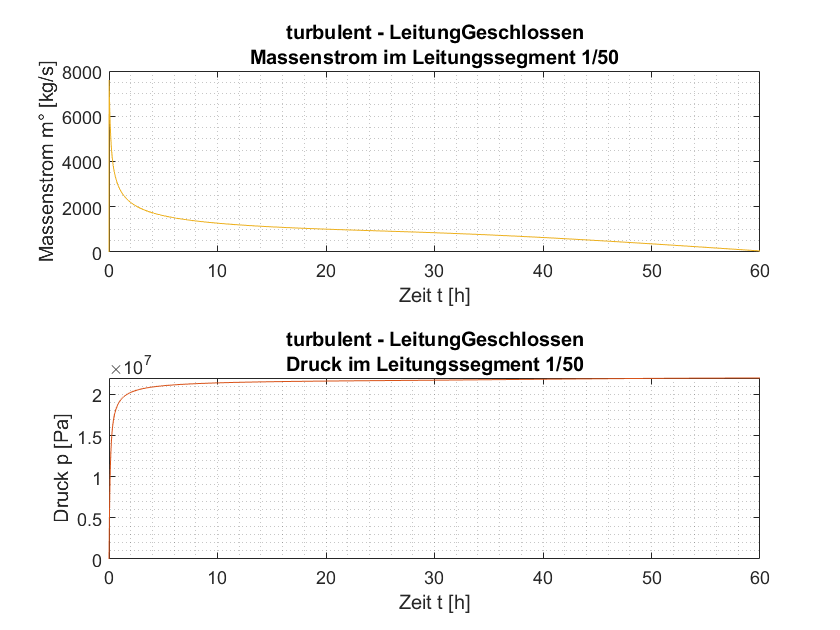

if plots_num == true
    if plots2d_Seg == true
        tiledlayout(2,1)
    %%% Massenstrom
        Massenstrom_Y_solver_SEG=nexttile;
        plot(Massenstrom_Y_solver_SEG,xAchse_num,Y_solver(i_Sim,:)','Color',farbe_num_m)
        title({Stroemungsart + " - " + LeitungEnde ; "Massenstrom im Leitungssegment " + i_Sim + "/" + n})
        grid minor
        xlabel(xAchseLabel)
        ylabel('Massenstrom m° [kg/s]')
    
    %%% Druck
        Druck_Y_solver_SEG=nexttile;
        plot(Druck_Y_solver_SEG,xAchse_num,Y_solver(n+i_Sim,:),'Color',farbe_num_p)
        title({Stroemungsart + " - " + LeitungEnde ; "Druck im Leitungssegment " + i_Sim + "/" + n}) 
        grid minor
        xlabel(xAchseLabel)
        ylabel('Druck p [Pa]')
    else
        fprintf("Dieses Diagramm ist nicht ausgewählt!");
    end
else
    fprintf("Dieses Diagramm ist nicht ausgewählt!");
end

Visualisieren der Lösung über **alle** Leitungssegmente an **einem** spezifischen Simulationszeitpunkt

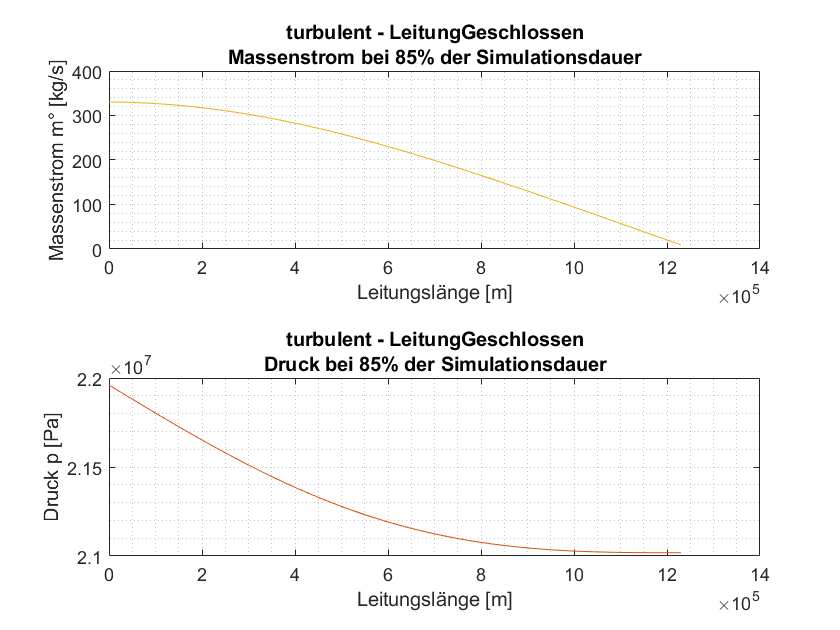

if plots_num == true
    if plots2d_t == true
        tiledlayout(2,1)
    %%% Massenstrom
        Massenstrom_Y_solver_TE=nexttile;
        plot(Massenstrom_Y_solver_TE,VLL,Y_solver(1:n,t_Sim),'Color',farbe_num_m)
        title({Stroemungsart + " - " + LeitungEnde ; "Massenstrom bei " + t_Sim_prznt + "% der Simulationsdauer"})
        grid minor
        xlabel('Leitungslänge [m]')
        ylabel('Massenstrom m° [kg/s]')
    
    %%% Druck
        Druck_Y_solver_TE=nexttile;
        plot(Druck_Y_solver_TE,VLL,Y_solver(n+1:2*n,t_Sim),'Color',farbe_num_p)
        title({Stroemungsart + " - " + LeitungEnde  "Druck bei " + t_Sim_prznt + "% der Simulationsdauer"})
        grid minor
        xlabel('Leitungslänge [m]')
        ylabel('Druck p [Pa]')
    else
        fprintf("Dieses Diagramm ist nicht ausgewählt!");
    end
else
    fprintf("Dieses Diagramm ist nicht ausgewählt!");
end

#### 3D-Plot der ode-Lösung

if plots_num == true
    if plots3d == true
    %%% Massenstrom Y_solver
        [T,N]=meshgrid(t_solver,VLL);
        figure('Name',"Verlauf Massenstrom - " + Stroemungsart + " - " + LeitungEnde + " - " + use_ODE)
        mesh(T,N,Y_solver(1:n,:))
        xlabel('Zeit t [h]');
        ylabel('Leitungslänge [m]');
        zlabel("Massenstrom [kg/s]"); 
        view([-41.400 36.600])
    
    %%% Druck Y_solver(n+1:2n)
        [T,N]=meshgrid(t_solver,VLL);
        figure('Name',"Verlauf Druck - " + Stroemungsart + " - " + LeitungEnde + " - " + use_ODE)
        mesh(T,N,Y_solver(n+1:2*n,:))
        xlabel('Zeit t [h]');
        ylabel('Leitungslänge [m]');
        zlabel("Druck [Pa]"); 
        view([-41.400 36.600])
    else
        fprintf("Dieses Diagramm ist nicht ausgewählt!");
    end
else
    fprintf("Dieses Diagramm ist nicht ausgewählt!");
end

Dieses Diagramm ist nicht ausgewählt!

### 4.3. Vergleich zwischen linearem DGL-System und ode-Lösungsverfahren

Visualisieren der Lösung für **ein** spezifisches Leitungssegment über die **gesamte** Simulationszeit

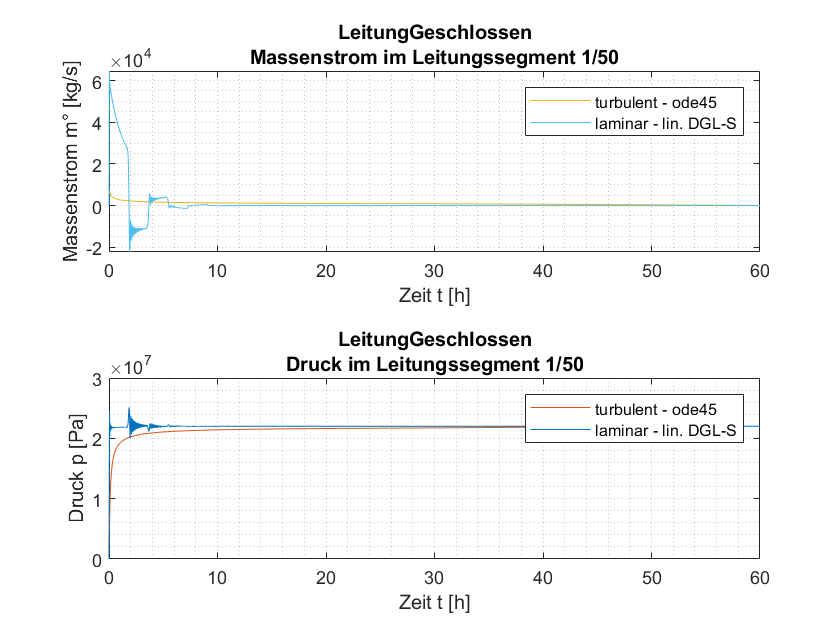

if plots_vergl_Seg==true
    tiledlayout(2,1)
%%% Massenstrom
    Massenstrom_Vergleich_SEG = nexttile;
    plot(Massenstrom_Vergleich_SEG,xAchse_num,Y_solver(i_Sim,:)','Color',farbe_num_m);
    hold on
    plot(Massenstrom_Vergleich_SEG,xAchse_lin,Y_lin1(i_Sim,:),'Color',farbe_lin_m);
    title({LeitungEnde;"Massenstrom im Leitungssegment " + i_Sim + "/" + n})
    grid minor
    xlabel(xAchseLabel)
    ylabel('Massenstrom m° [kg/s]')
    legend(Stroemungsart + " - " + use_ODE ,"laminar - lin. DGL-S")
    hold off

%%% Druck
    Druck_Vergleich_SEG = nexttile;
    plot(Druck_Vergleich_SEG,xAchse_num,Y_solver(n+i_Sim,:),'Color',farbe_num_p);
    hold on
    plot(Druck_Vergleich_SEG,xAchse_lin,Y_lin2(i_Sim,:),'Color',farbe_lin_p);
    title({LeitungEnde;"Druck im Leitungssegment " + i_Sim + "/" + n})
    grid minor
    xlabel(xAchseLabel)
    ylabel('Druck p [Pa]')
    legend(Stroemungsart + " - " + use_ODE ,"laminar - lin. DGL-S")
    hold off
else
    fprintf("Dieses Diagramm ist nicht ausgewählt!");
end

Visualisieren der Lösung über **alle** Leitungssegmente an **einem** spezifischen Simulationszeitpunkt

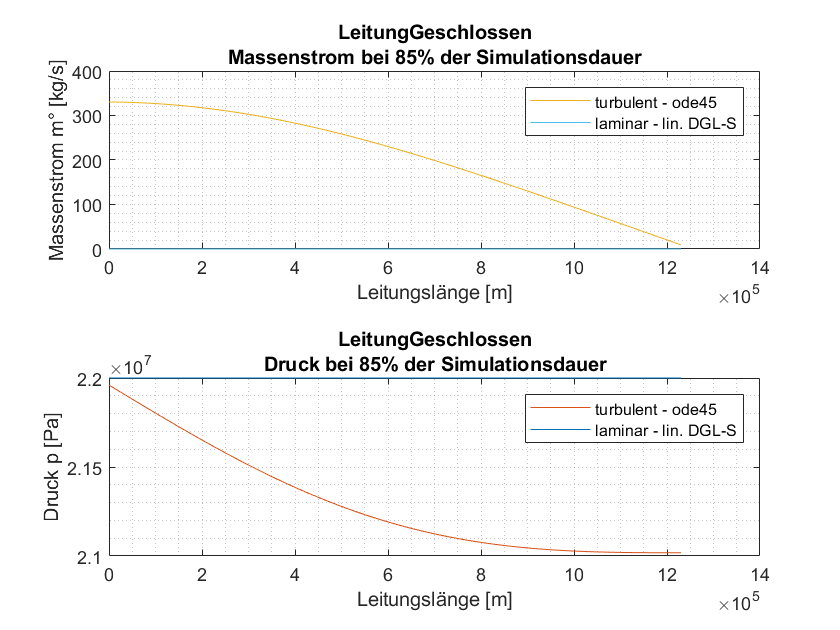

if plots_vergl_t==true
    tiledlayout(2,1)
%%% Massenstrom
    Massenstrom_Vergleich_TE = nexttile;
    plot(Massenstrom_Vergleich_TE,VLL,Y_solver(1:n,t_Sim),'Color',farbe_num_m);
    hold on
    plot(Massenstrom_Vergleich_TE,VLL,Y_lin1(:,t_Sim),'Color',farbe_lin_m);
    title({LeitungEnde;"Massenstrom bei " + t_Sim_prznt + "% der Simulationsdauer"})
    grid minor
    xlabel('Leitungslänge [m]')
    ylabel('Massenstrom m° [kg/s]')
    legend(Stroemungsart +" - "+ use_ODE ,"laminar - lin. DGL-S")
    hold off

%%% Druck
    Druck_Vergleich_TE = nexttile;
    plot(Druck_Vergleich_TE,VLL,Y_solver(n+1:2*n,t_Sim),'Color',farbe_num_p);
    hold on
    plot(Druck_Vergleich_TE,VLL,Y_lin2(:,t_Sim),'Color',farbe_lin_p);
    title({LeitungEnde;"Druck bei " + t_Sim_prznt + "% der Simulationsdauer"})
    grid minor
    xlabel('Leitungslänge [m]')
    ylabel('Druck p [Pa]')
    legend(Stroemungsart + " - " + use_ODE ,"laminar - lin. DGL-S")
    hold off
else
    fprintf("Dieses Diagramm ist nicht ausgewählt!");
end